% Declaring variables to derive the state space representation of system
% M is the Mass of cart
% m1 is the mass attached to pendulum 1
% m2 is the mass attached to pendulum 2
% l1 is the length of pendulum 1
% l2 is the length of pendulum 2
% g is the accleration due to gravity 
syms M m1 m2 l1 l2 g;

% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;


% Declaring the A matrix of the system
A = [0 1 0 0 0 0;
     0 0 -(m1*g)/M 0 -(m2*g)/M 0;
     0 0 0 1 0 0;
     0 0 -((M+m1)*g/(M*l1)) 0 -(m2*g)/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -(m1*g)/(M*l2) 0 -((M+m2)*g/(M*l2)) 0];

% Declaring the B matrix of the system
B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
% disp(B)

% Declaring the C matrix
C = eye(6);
D = [0; 0; 0; 0; 0; 0];


ctrb_sym = [B A*B (A^2)*B (A^3)*B (A^4)*B (A^5)*B];

% The part for checking the rank and determinant of controllability matrix after 
% evaluating the system as per the values of system properties 
ctrb_val = subs(ctrb_sym, {M, m1, m2, l1, l2, g}, {M_val, m1_val, m2_val, l1_val, l2_val, 9.81});
disp("The controllability matrix obtained is")

The controllability matrix obtained is


disp(simplify(ctrb_val))

$$\left(\begin{array}{cccccc} 0 & \frac{1}{1000} & 0 & -\frac{2943}{20000000} & 0 & \frac{56779299}{400000000000}\\ \frac{1}{1000} & 0 & -\frac{2943}{20000000} & 0 & \frac{56779299}{400000000000} & 0\\ 0 & \frac{1}{20000} & 0 & -\frac{12753}{400000000} & 0 & \frac{181886229}{8000000000000}\\ \frac{1}{20000} & 0 & -\frac{12753}{400000000} & 0 & \frac{181886229}{8000000000000} & 0\\ 0 & \frac{1}{10000} & 0 & -\frac{22563}{200000000} & 0 & \frac{499465359}{4000000000000}\\ \frac{1}{10000} & 0 & -\frac{22563}{200000000} & 0 & \frac{499465359}{4000000000000} & 0 \end{array}\right)$$


% Rank of controlability matrix as per the values of system properties
disp("The rank of controlability matrix after putting the system properties is: ")

The rank of controlability matrix after putting the system properties is: 


disp(rank(ctrb_val))

     6




% Checking and printing if the system, 
% with the given parameters of part D, is controllable
if(rank(ctrb_val == 6))
    disp("The controllability matrix is full rank, hence the system is controllable")
else
    disp("The controllability matrix is rank deficient, hence the system is not controllable")
end

The controllability matrix is full rank, hence the system is controllable





% Defining the Q and R matrices for LQR controller
Q = [10  0  0  0  0  0;
     0  10  0  0  0  0;
     0   0 100 0  0  0;
     0   0  0  1  0  0;
     0   0  0  0 100 0;
     0   0  0  0  0  1];

R = 0.001;

% Taking the A and B matrices as per the specified system parameters in
% part D
A_val = [0 1 0 0 0 0;
     0 0 -(m1_val*9.81)/M_val 0 -(m2_val*9.81)/M_val 0;
     0 0 0 1 0 0;
     0 0 -((M_val+m1_val)*9.81/(M_val*l1_val)) 0 -(m2_val*9.81)/(M_val*l1_val) 0;
     0 0 0 0 0 1;
     0 0 -(m1_val*9.81)/(M_val*l2_val) 0 -((M_val+m2_val)*9.81/(M_val*l2_val)) 0];


% Declaring the B matrix of the system
B_val = [0; 1/M_val; 0; 1/(M_val*l1_val); 0; 1/(M_val*l2_val)];

% Finding the optimal feedback gain K for the LQR controller, and R_soln
% corresponding to the solution of Ricatti equation and the poles of the
% closed loop control system
[K, R_soln, poles] = lqr(A_val,B_val,Q,R);

% Making the closed loop system after finding the optimal 'K' feedback gain 
lqr_sys = ss(A_val-(B_val*K), B_val, C, D);

% Initial condition
x_0 = [0; 0; 0.5; 0; 0.6; 0];

% The plot for the linearized system before applying LQR control
% disp("The plot for the linearized system before applying LQR control")
% figure
% initial(orig_sys, x_0)

% The plot for the linearized system after applying LQR control
disp("The plot for the linearized system after applying LQR control")

The plot for the linearized system after applying LQR control


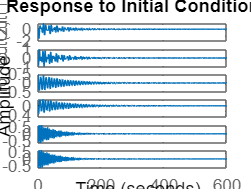

figure
initial(lqr_sys, x_0)




% Using Lyapunov's indirect method to certify stability of the closed-loop
% system
disp("The poles of the closed loop control system are")

The poles of the closed loop control system are


disp(poles)

  -0.0102 + 0.7277i
  -0.0102 - 0.7277i
  -0.0178 + 1.0423i
  -0.0178 - 1.0423i
  -0.2066 + 0.2023i
  -0.2066 - 0.2023i




% Initializing a count to keep track of stable poles
count_stable_pole = 0;

% Checking the real part of each pole
for  i = 1 : length(poles)
    if(real(poles(i)) < 0)
        count_stable_pole = count_stable_pole + 1;
    end
end

% Printing the stability of the system based on the location of poles
if(count_stable_pole == 6)
    disp("As all poles are in the left half plane, the closed loop system is stable")
else
    disp("As all the poles are not in the left half plane, the closed loop system is not stable")
end

As all poles are in the left half plane, the closed loop system is stable
